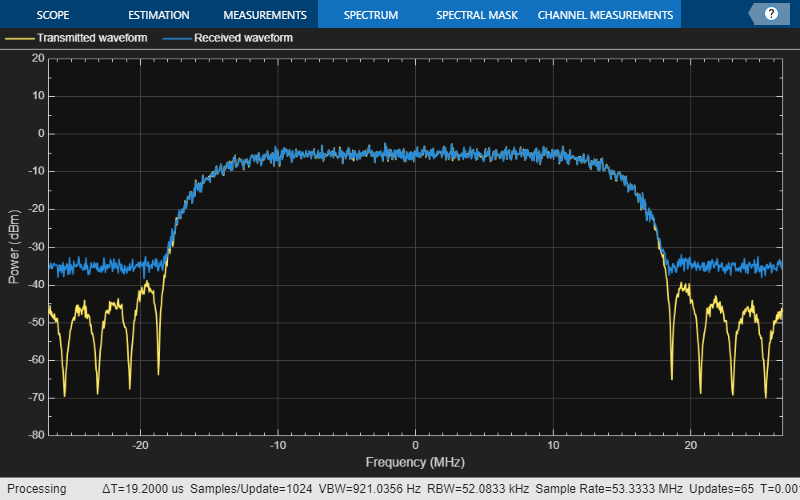

parameters;
                             

[data,txOut,rxIn,rxParams]=HelperDVBS2RxInputGenerate(cfgDVBS2,simParams);


%Received signal constellation plot
txConst = comm.ConstellationDiagram(Title = "Transmitted data", ...
    AxesLimits = [-1 1], ...
    ShowReferenceConstellation = false, ...
    SamplesPerSymbol = simParams.sps);
txConst(rxIn(1:rxParams.plFrameSize*simParams.sps));

% Transmitted and received signal spectrum visualization
Rsymb = simParams.chanBW/(1 + cfgDVBS2.RolloffFactor);
Fsamp = Rsymb*simParams.sps;
specAn = spectrumAnalyzer(SampleRate = Fsamp, ...
    ChannelNames = ["Transmitted waveform" "Received waveform"], ...
    ShowLegend = true);
specAn([txOut, rxIn(1:length(txOut))]);



%data=raw_data_generator(cfgDVBS2.MinNumPackets); 
% waveform = cfgDVBS2(data); % generate the signal
% waveform_noise=awgn_channel(waveform); % awgn channel


% sps = cfgDVBS2.SamplesPerSymbol;
% constel = comm.ConstellationDiagram('ColorFading',true, ...
%     'ShowTrajectory',0, ...
%     'SamplesPerSymbol',sps, ...
%     'ShowReferenceConstellation',false, ...
%     'NumInputPorts',2,...
%     'XLimits',[-1.5 1.5], 'YLimits',[-1.5 1.5]);
% plHeaderLen = 90*sps;           % PL header length
% constel(waveform(plHeaderLen+1:end),waveform_noise(plHeaderLen+1:end));
% release(constel);
% 
% BW = 36e6;                 % Typical satellite channel bandwidth
% Fsym = BW/(1+cfgDVBS2.RolloffFactor);
% Fsamp = Fsym*sps;
% scope = spectrumAnalyzer('SampleRate',Fsamp);
% scope(waveform,waveform_noise)






